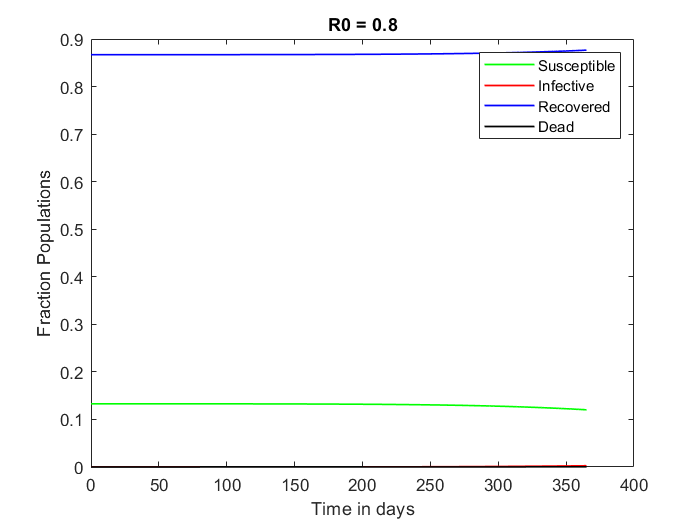

S = zeros(365000,1);
I = zeros(365000,1);
R = zeros(365000,1);
D = zeros(365000,1);
N = 1e6;
% fractional population
R0 = 0.867;
I(1) = 10/N;
R(1) = R0;
D(1) = 0;
S(1) = 1-R(1)-I(1);
b = 5e-7;
g = 0.05;
m = 0.05;
delt = 0.001; % time step 
t = 0:delt:365;
% apply forward euler
for n = 1:365000
    dSdt = -b*N*I(n)*S(n);
    dIdt = (b*N*S(n)-g)*I(n);
    dRdt = (g)*I(n);
    S(n + 1) = S(n) + dSdt * delt;
    I(n + 1) = I(n) + dIdt * delt;
    R(n + 1) = R(n) + dRdt * delt * (1-m);
    D(n + 1) = m*(R(n+1)-R0)/(1-m);
end
plot(t,S,'g','LineWidth',1.0);
hold on
plot(t,I,'r','LineWidth',1.0);
plot(t,R,'b','LineWidth',1.0);
plot(t,D,'k','LineWidth',1.0);
ylabel('Fraction Populations');
xlabel('Time in days');
title('R0 = 0.8');
legend('Susceptible','Infective','Recovered', 'Dead' );
hold off

total_fractional_deaths = D(end)

total_fractional_deaths = 5.0202e-04